# Reading images

The script describes simple ways to read images using MATLAB.

## Reading Images

% Reading images
img=imread("../../data/data_curling/curling_frame.png");  % Image from curling

Once you read an image, it is often important to check a few details of the image variable (`img`). This can be done 

whos img

  Name         Size                  Bytes  Class    Attributes

  img       1080x1920x3            6220800  uint8              



Here the image is stored as **uint8** variable. Also, there are three color panels. We will visualise each of these panels next.

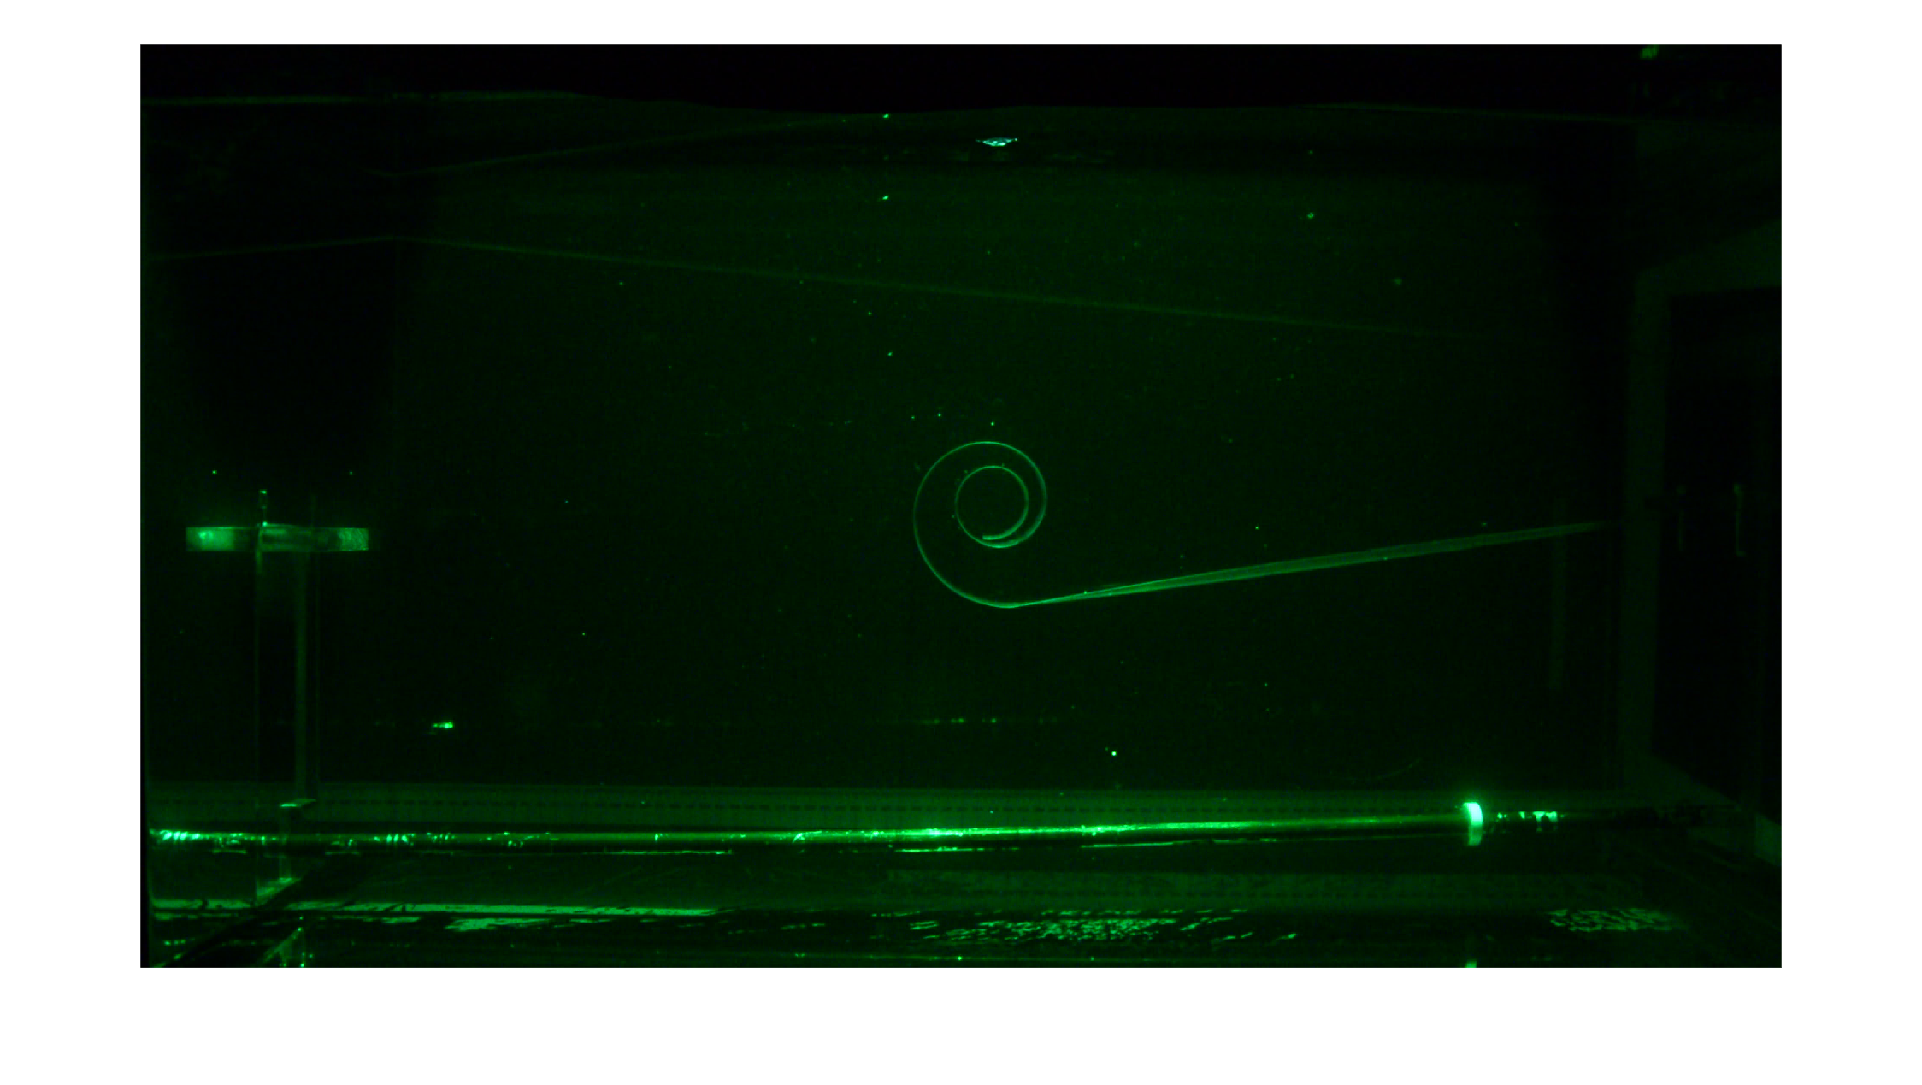

% visualising the RGB image
figure(1);
imshow(img)

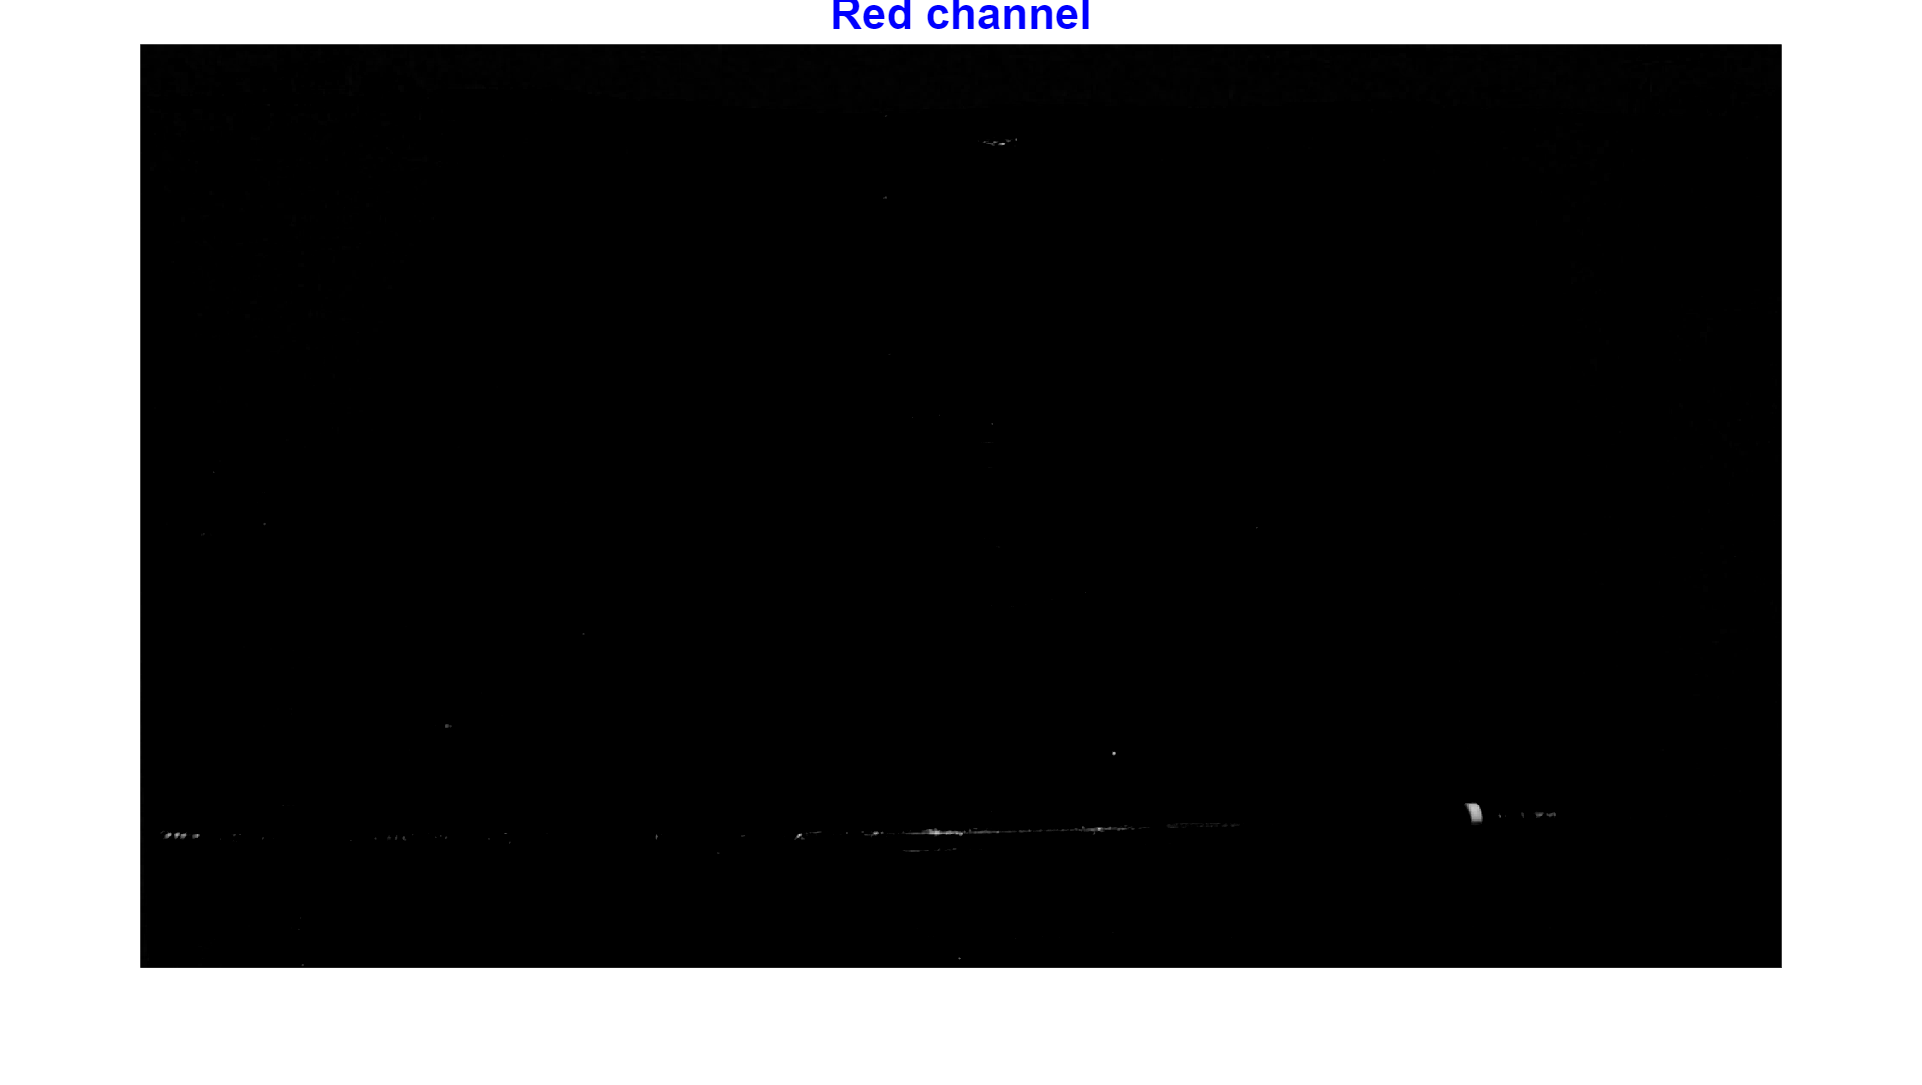

% Extracting individual channels
img_red=img(:,:,1);   % red channel
img_green=img(:,:,2); % green channel
img_blue=img(:,:,3);  % blue channel

image_viewer(img_red,"Red channel")       % visualising the red channel

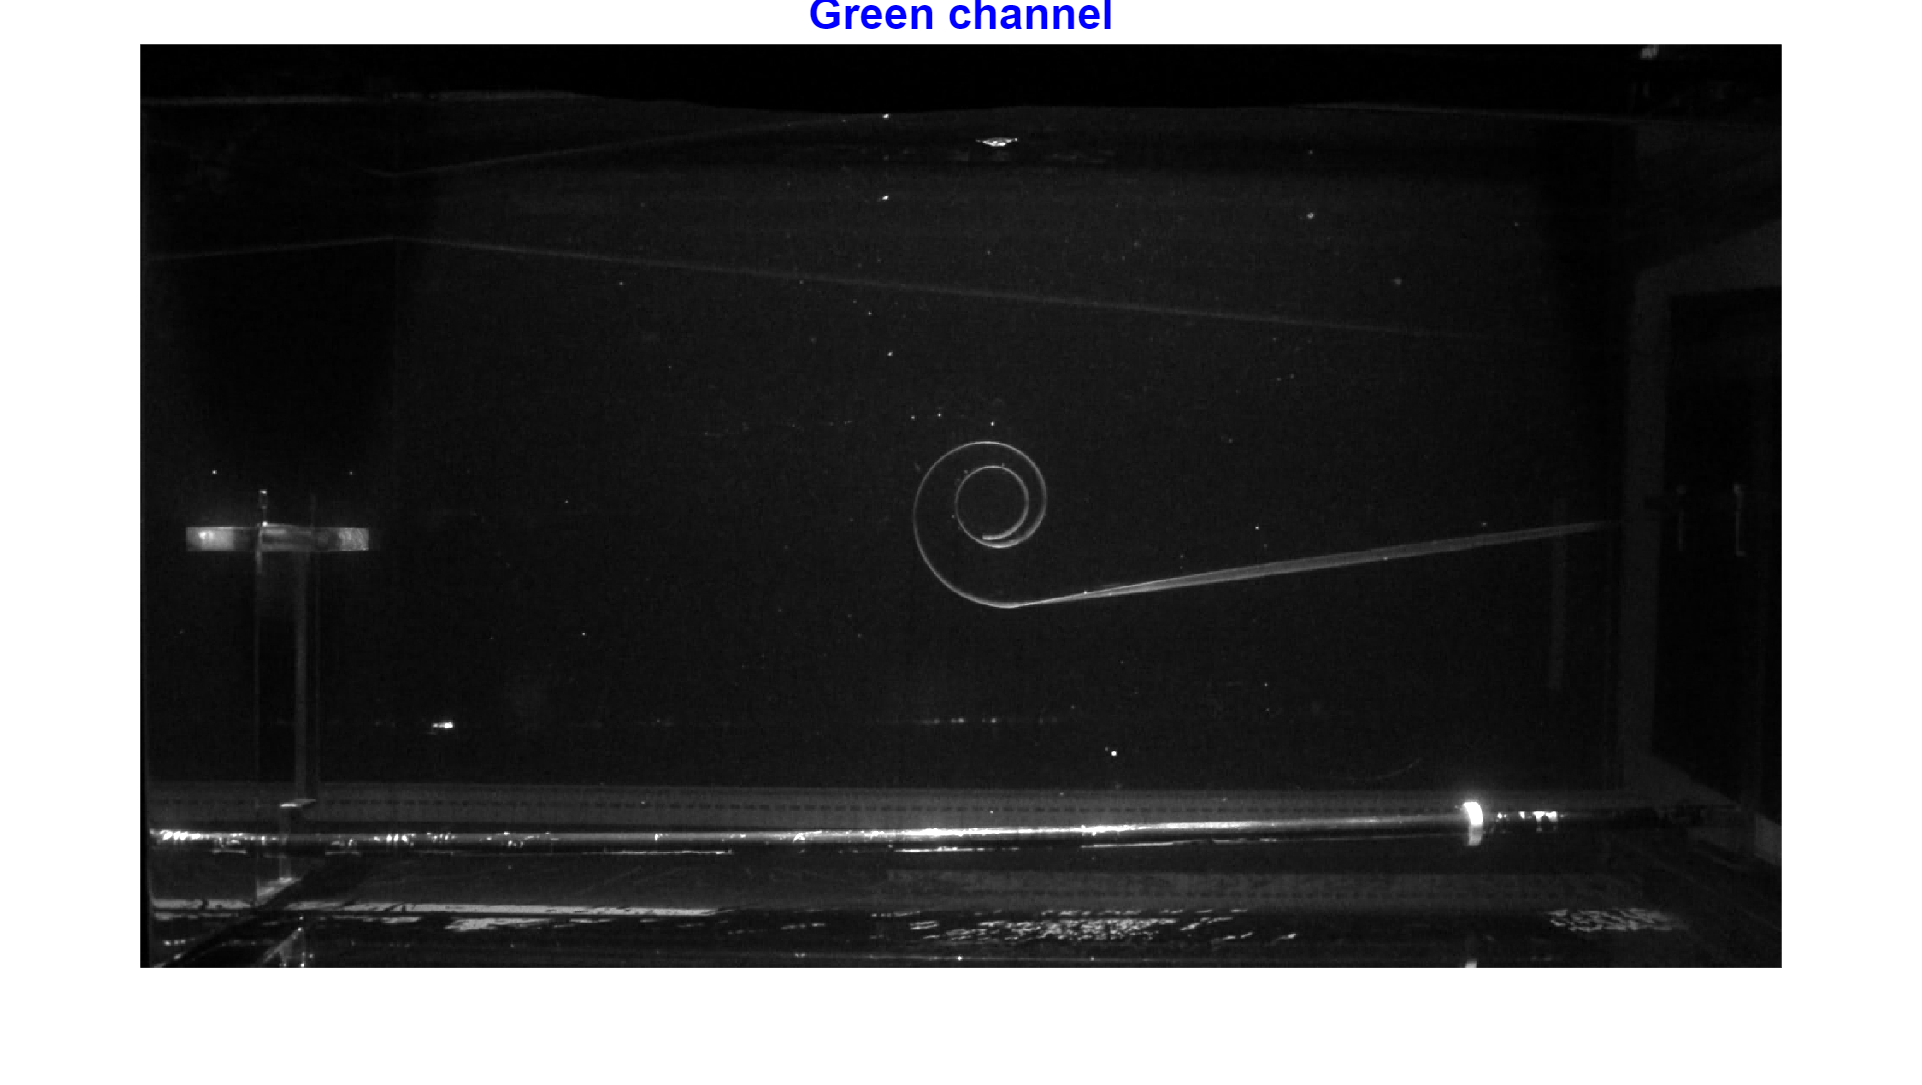

image_viewer(img_green,"Green channel")   % visualising the green channel

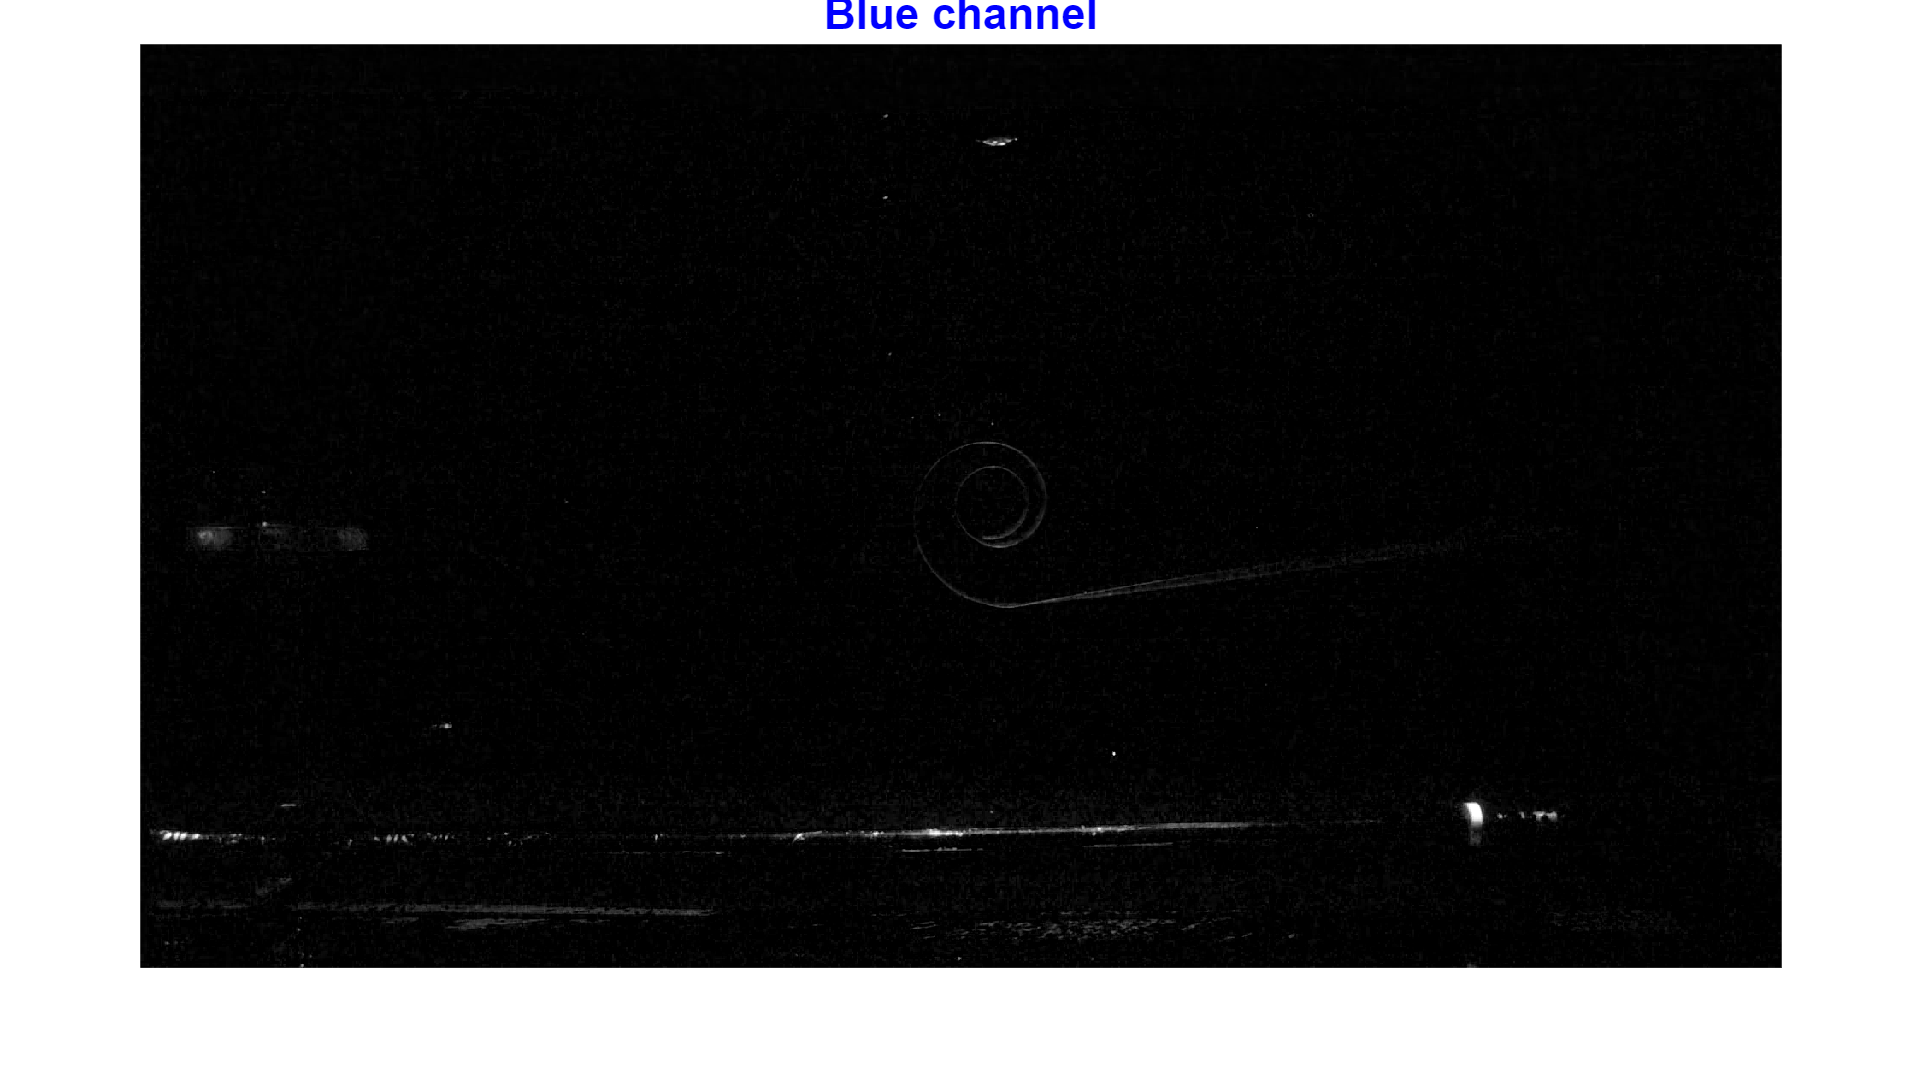

image_viewer(img_blue,"Blue channel")     % visualising the blue channel

## Using GUI tool

In MATLAB, there are various GUI tools to inspect the images. I used to use *imtool*. In current versions, the app to use would be imageViewer.

## Task

% open an image using the GUI
% try to inspect the image

% % opening using """imtool"""
% imtool(img)

% % opening using """imageViewer"""
% imageViewer(img)

## Metadat related to an image

Sometime if you need to extract more information (metadata) from an image. In such cases, functions like **imageinfo** might come handy.

% filename="../../data/data_curling/curling_frame.png";
% imageinfo(filename)
close all;clear;clc